# Supplementary figure 3: Signal-to-noise ratio and memory capacity for different value of $P$ and $D$

Signal-to-noise ratio and memory capacity for P = D = 0.1, P = 0.1 & D = 0.3, and P = 0.3 & D = .1

export: 10.5-7

clear; clc; 
load Files\weight_matrix\SupFig3\SNR_Capacity.mat

## Figure A: $P = D = 0.1$

plot_SNR(etas, SNR_s1_PDdot1, SNR_M100_PDdot1)
plot_capacity(asM, Capacity_M_PDdot1, asS, Capacity_s_PDdot1)

## Figure B: $P = 0.1$ & $D = 0.3$

plot_SNR(etas, SNR_s1_Pdot1Ddot3, SNR_M100_Pdot1Ddot3)
plot_capacity(asM, Capacity_M_Pdot1Ddot3, asS, Capacity_s_Pdot1Ddot3)

## Figure C: $P = 0.3$ & $D = 0.1$

plot_SNR(etas, SNR_s1_Pdot3Ddot1, SNR_M100_Pdot3Ddot1)
plot_capacity(asM, Capacity_M_Pdot3Ddot1, asS, Capacity_s_Pdot3Ddot1)

## Figure D: memory capacity as function of $P$ for cases $P=D$ and $s=1$

$\eta$: how far back in the past the environment was explored

$M$: the number of neurons that encode the same position

In general, there is not an analytical formula for the memory capcity due the complex express of the variance. However, for a special case $P=D$ and $s= 1$, the terms $B_\eta$ and $C_\eta$ will be cancel $\forall \eta$, and the SNR can be written as $SNR = \frac{a_\eta}{\sqrt{V_\eta}} = \frac{a_\eta}{\sqrt{A_\eta}}$, where $a_\eta = P(1-2P)^\eta$ and $A_\eta = \frac 1M\Big(\frac{P}{8(1-P)}-\frac{P^2(1-2P)^{2\eta}}{2}\Big)$.

By setting $SNR = 1$ we can find the the critical value of $\eta$, the capcity of storage memory. In this case, $\eta_{max} = -\frac{1}{2}\log_{1-2P}(4P(1-P)(2M-1))$.

Now we are plot the storage capacity as function of $P$ for different value of $M$.

Export figure setup: 10.5        7

84-56

clear; clc;
load Files\weight_matrix\SupFig3\max_P_M.mat



cols = ["k-", "r-", "b-"];

figure
hold on
set(gca, 'YScale', 'log')
set(gca, 'XScale', 'log')
for i = 1:length(M_seq)
    plot(P{i}, capacities{i}, cols(i), "LineWidth", 4.5)    
end
hold off
legend(["M = 10", "M = 10^2", "M = 10^3"], "Location", "northeast")
legend box off
box off
fig_config(70)

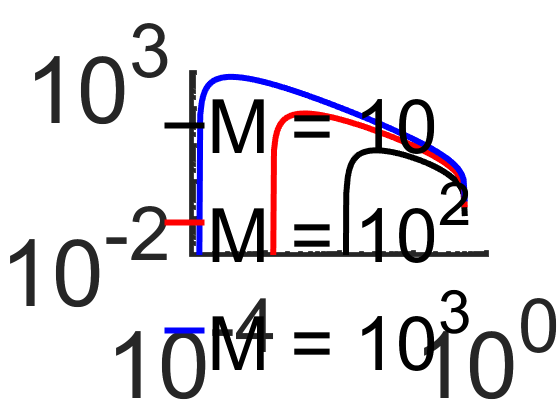

xlim([1e-4, 1])
xticks([1e-4, 1e-3, 1e-2, 1e-1, 1])
xticklabels(["10^{-4}", "", "", "", "10^0"])
ylim([1e-2, 1e3])
yticks([1e-2, 1e-1, 1e0, 1e1, 1e2, 1e3])
yticklabels(["10^{-2}", "", "", "", "", "10^3"])

## Figure E: For given $M$, find the value of $P$ such that the capacity is max.

Export figure setup: 6-4

84-56

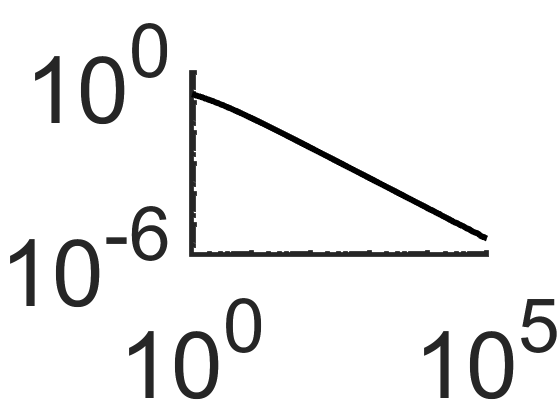

loglog(M_seq_amx, max_P, "k-", "LineWidth", 4.5)
fig_config(70)
xlim([1e0, 1e5])
xticks([1e0, 1e1, 1e2, 1e3, 1e4, 1e5])
xticklabels(["10^{0}", "", "", "", "", "10^5"])
ylim([1e-6, 1e0])
yticks([1e-6, 1e-5, 1e-4, 1e-3, 1e-2, 1e-1, 1e0])
yticklabels(["10^{-6}", "", "", "", "", "", "10^0"])
box off

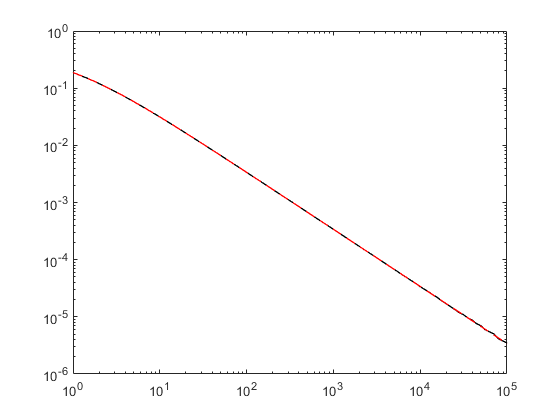

myfun = @(p, M) (1-2*p)^2*log(1-2*p) + 2*p*(1-p)*log(4*(2*M+1)*(p-p^2));

p_opt = zeros(1, length(M_seq_amx));
p_min = @(M) (1-sqrt((2*M)/(2*M+1)))/2;
for i = 1:length(M_seq_amx)
    fun = @(p) myfun(p, M_seq_amx(i));
    st_point = p_min(M_seq_amx(i)) * 2;
    p_opt(i) = fzero(fun, st_point + 0.00001);
    %p_opt(i) = fzero(fun, max_P(i) + 0.00001);
end
%p_opt(1) = max_P(1);

loglog(M_seq_amx, max_P, "k-", "LineWidth", 1)
hold on
loglog(M_seq_amx, p_opt, "r--", "LineWidth", 1)
hold off

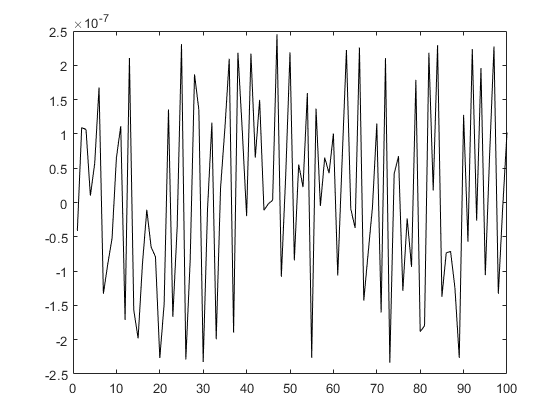



plot(max_P-p_opt, "k")

## A   uxiliar Functions

function plot_SNR(etas, SNR_s1, SNR_M100)
    figure
    h = loglog(etas + 1, SNR_s1+0.01, "-", "LineWidth", 4.5);
    set(h, {'color'}, {[1.0000, 0.7294, 0.7294]; [1, 0, 0]; [0.6549, 0, 0]});
        yline(1, "--k", "LineWidth", 2.5)
    %{
    hold on
    qw{1} = plot(nan, "-", "LineWidth", 4.5, "Color", "[1.0000, 0.7294, 0.7294]");
    qw{2} = plot(nan, "-", "LineWidth", 4.5, "Color", "[1, 0, 0]");
    qw{3} = plot(nan, "-", "LineWidth", 4.5, "Color", "[0.6549, 0, 0]"); % You can add an extra element too
    legend([qw{:}], {"M = 1", "M = 10", "M = 100"}, 'location', 'northeast')
    hold off
    legend boxoff
    %}
    box off
    ylim([1e-2, 1e2])
    yticks([1e-2, 1e-1, 1e0, 1e1, 1e2])
    yticklabels(["10^{-2}", "", "", "", "10^{2}"])
    xlim([0, 1e2])
    xticks([1e0, 1e1, 1e2])
    xticklabels(["10^{0}", "", "10^{2}"])
    fig_config(80)
    
    figure
    h = loglog(etas + 1, SNR_M100+0.01, "-", "LineWidth", 4.5);
    set(h, {'color'}, {[0.7098, 0.8196, 0.8863]; [0.0157, 0.4314, 0.7686]; [0.0157, 0.2431, 0.4902]});
    yline(1, "--k", "LineWidth", 2.5)
    %{
    hold on
    qw{1} = plot(nan, "-", "LineWidth", 4.5, "Color", "[0.7098, 0.8196, 0.8863]");
    qw{2} = plot(nan, "-", "LineWidth", 4.5, "Color", "[0.0157, 0.4314, 0.7686]");
    qw{3} = plot(nan, "-", "LineWidth", 4.5, "Color", "[0.0157, 0.2431, 0.4902]"); % You can add an extra element too
    legend([qw{:}], {'s = 0.1','s = 0.5','s = 1'}, 'location', 'northeast')
    hold off
    legend boxoff
    %}
    ylim([1e-2, 1e2])
    yticks([1e-2, 1e-1, 1e0, 1e1, 1e2])
    yticklabels(["10^{-2}", "", "", "", "10^{2}"])
    xlim([0, 1e2])
    xticks([1e0, 1e1, 1e2])
    xticklabels(["10^{0}", "", "10^{2}"])
    box off
    fig_config(80)
end


function plot_capacity(asM, Capacity_M, asS, Capacity_s)

    figure
    h = loglog(asM, Capacity_M, "-", "LineWidth", 4.5);

    set(h, {'color'}, {[0, 0, 0]; [1, 0, 0]});
    ylim([0.5 , 300])
    %{
    hold on
    qw{1} = plot(nan, "-", "LineWidth", 4.5, "Color", "[0 0 0]");
    qw{2} = plot(nan, "-", "LineWidth", 4.5, "Color", "[1 0 0]");
    legend([qw{:}], {'s = 0.25','s = 1'}, 'location', 'northwest')
    legend boxoff
    hold off
    %}
    box off
    fig_config(80)
    ylim([1e-1, 1e3])
    yticks([1e0, 1e1, 1e2])
    yticklabels(["10^{0}", "", "10^{2}"])
    xlim([1e0, 1e4])
    xticks([1e0, 1e1, 1e2, 1e3, 1e4])
    xticklabels(["10^{0}", "", "", "", "10^{4}"])
    
    figure
    h = loglog(asS, Capacity_s, "-", "LineWidth", 4.5);
    ylim([1e0, 1e5])
    xlim([1e-2, 1e0])
    xticks([1e-2, 1e-1, 1e0])
    xticklabels(["10^{-2}",  "", "10^{0}"])
    yticks([1e0, 1e1, 1e2, 1e3, 1e4, 1e5])
    yticklabels(["10^{0}", "", "", "", "", "10^{5}"])
    set(h, {'color'}, {[0, 0, 1]; [0, 0, 0]});
    %{
    hold on
    qw{1} = plot(nan, "-", "LineWidth", 4.5, "Color", "[0, 0, 1]");
    qw{2} = plot(nan, "-", "LineWidth", 4.5, "Color", "[0 0 0]");
    legend([qw{:}], {'M = 1e2','M = 1e4'}, 'location', 'northeast')
    hold off
    legend box off
    %}
    box off
    fig_config(80)
end